# 2.12 Lab 3: Euler Transforms

Create a set of three rotation matrices. One which represents a $\phi=25^\circ$ about the $z$ axis, another which represents a rotation of $\theta=45^\circ$ about the $x$ axis, and a final matrix for $\psi=60^\circ$ about the $z$ axis ($R_{z1}$, $R_x$, $R_{z2}$ respectively). Note that in MATLAB, you can use sind(), cosd(), and tand() with input arguments in degrees instead of radians.

% MODIFY CODE HERE
% Rz1 = ?
% Rx = ?
% Rz2 = ?

Rz1 =     0.9063   -0.4226         0
    0.4226    0.9063         0
         0         0    1.0000


Rx =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


Rz2 =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


Now, perform two sets of transformations with these matrices, $R1$ and $R2$. In $R1$, we want to perform the $60^\circ$ rotation about $z$ first, then a $45^\circ$ rotation about the $x$ axis, and then a 25 rotation about the new $z$ axis. In $R2$, you'll perform the $25^\circ$ rotation about the $z$ axis first, then a $45^\circ$ rotation about the $x$ axis, and then a $60^\circ$ rotation about the new $z$ axis. Apply both of these transforms to a coordinate frame with **n** = [1, 0, 0]', **t** = [0, cosd(15), sind(15)]', and **b** = [0,-sind(15), cosd(15)]'. 

Fill out the code below to visualize these two transformations. Note that the red axis represents the coordinate frame's **n** vector, the green axis represents **t**, and the blue axis represents **b**.

**Question:** *Fill out the code below to visualize these two transformations. Note that the red axis represents the coordinate frame's ****n**** vector, the green axis represents ****t****, and the blue axis represents ****b****. What is the orientation of the initial [n,t,b] coordinate frame relative to the world frame?*

n = [1, 0, 0]';
t = [0, cosd(15), sind(15)]';
b = [0, -sind(15), cosd(15)]';
R0 = [n,t,b];

R1 =     0.1944   -0.7663    0.6124
    0.9343   -0.0456   -0.3536
    0.2988    0.6409    0.7071


R2 =     0.1944   -0.9343    0.2988
    0.7663   -0.0456   -0.6409
    0.6124    0.3536    0.7071


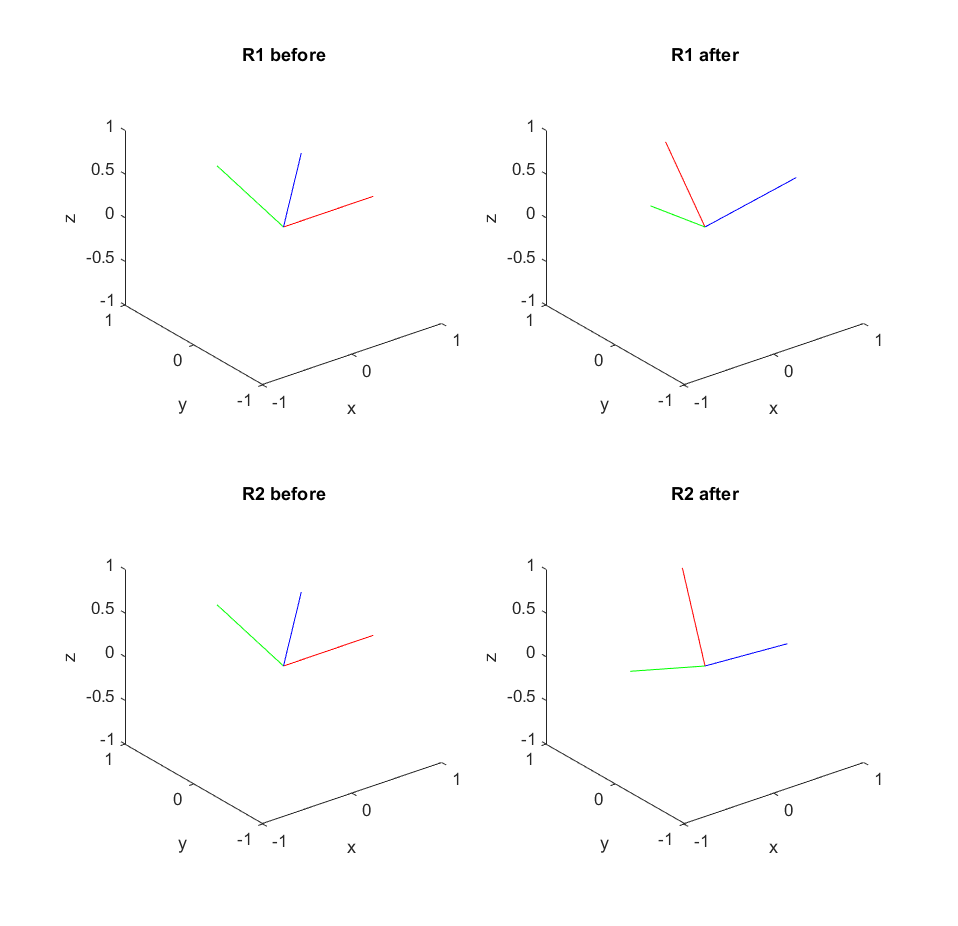

% MODIFY CODE HERE
% R1 = ?
% R2 = ?

subplot(2,2,1)
% MODIFY CODE HERE
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation before applying R1, R0))
plotTransforms([0 0 0],rotm2quat(R0))
xlabel('x')
ylabel('y')
zlabel('z')
title('R1 before')
axis([-1 1 -1 1 -1 1])

subplot(2,2,2)
% MODIFY CODE HERE
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation after applying R1, R0*R1))
plotTransforms([0 0 0],rotm2quat(R0*R1))
xlabel('x')
ylabel('y')
zlabel('z')
title('R1 after')
axis([-1 1 -1 1 -1 1])

subplot(2,2,3)
% MODIFY CODE HERE
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation before applying R2, R0))
plotTransforms([0 0 0],rotm2quat(R0))
xlabel('x')
ylabel('y')
zlabel('z')
title('R2 before')
axis([-1 1 -1 1 -1 1])

subplot(2,2,4)
%plotTransforms([0 0 0],rotm2quat(insert the frame's orientation after applying R2, R0*R2))
plotTransforms([0 0 0],rotm2quat(R0*R2))
xlabel('x')
ylabel('y')
zlabel('z')
title('R2 after')
axis([-1 1 -1 1 -1 1])

**Question**: *What are the ****n****, ****t****, and ****b ****vectors for the final coordinate frames? Are they different? Why do these two transformations lead to different orientations? Do you know of any alternate ways that these transformations could be represented?*

Version 1: Cormac O'Neill, 2021